# **Absorption in air**

**2023-03-24**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

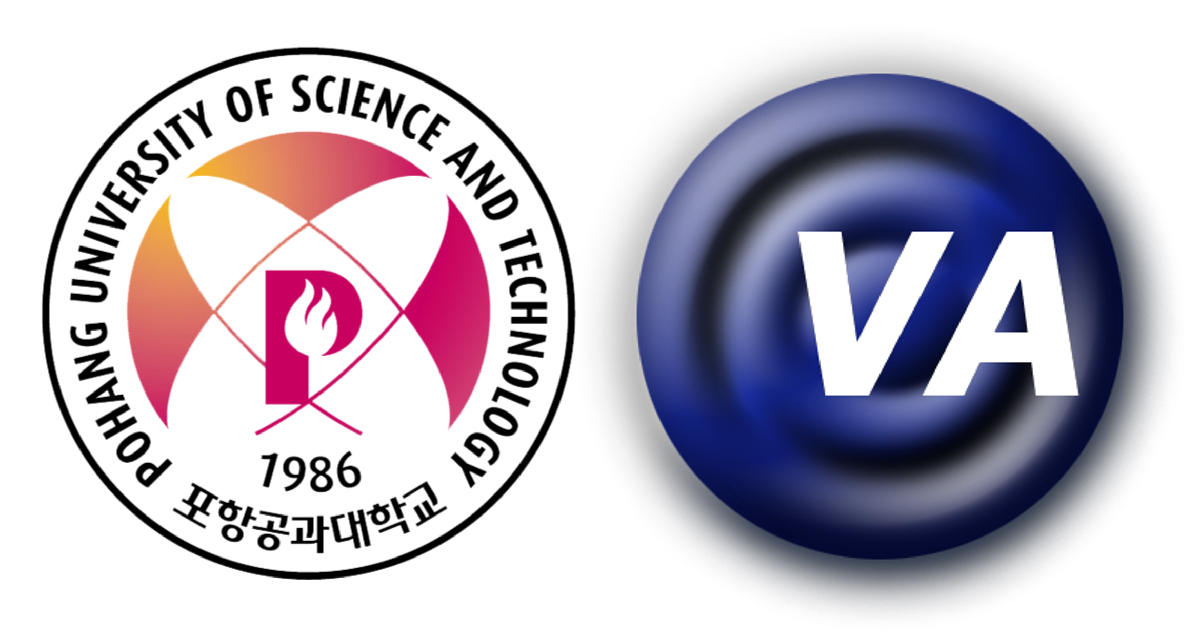

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

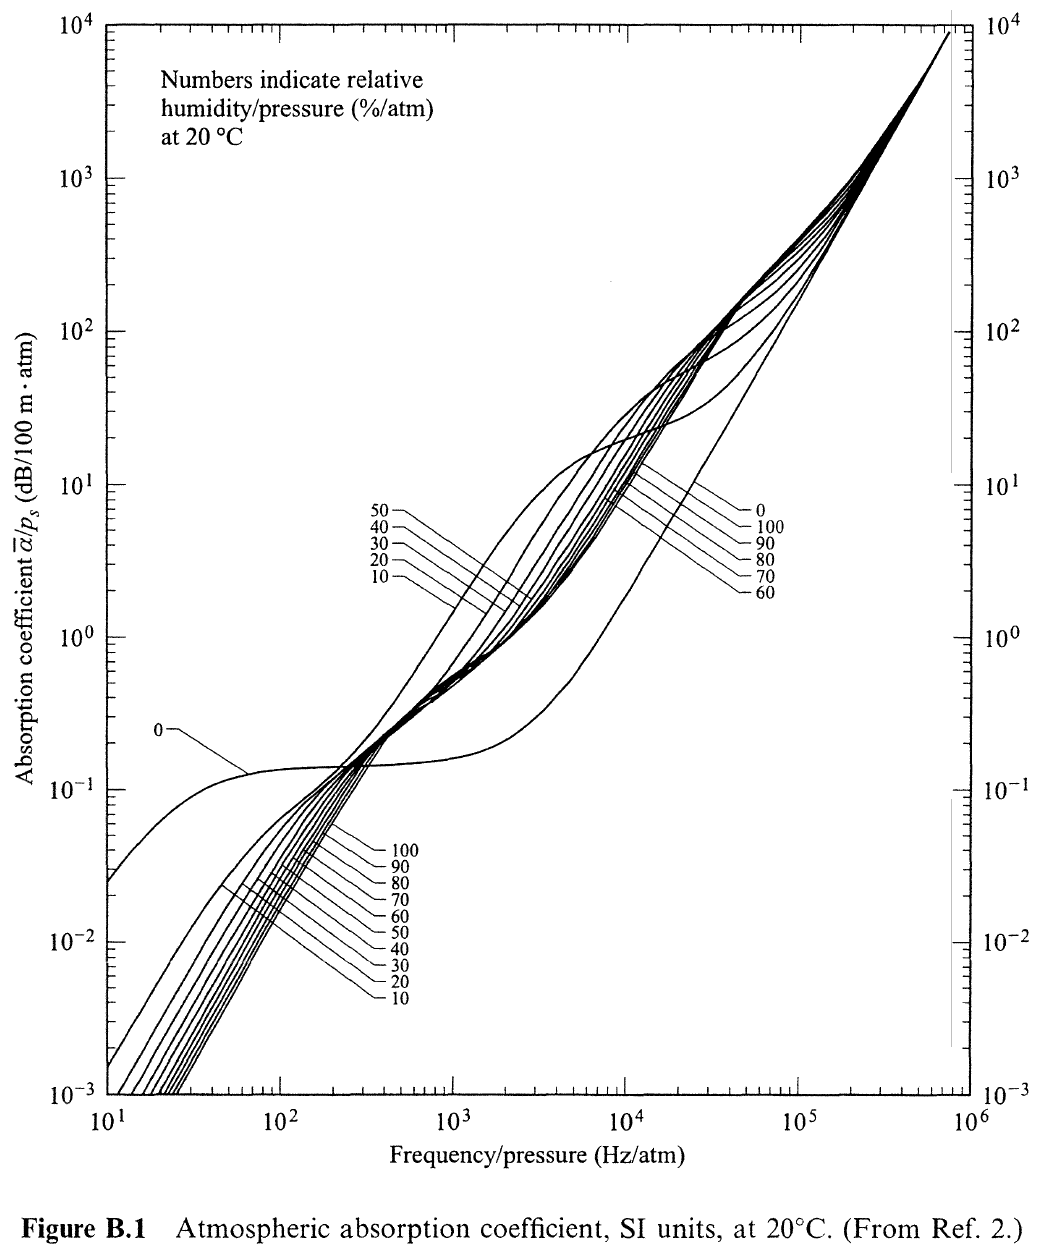

This code is originally written by [Edward Zechmann](https://kr.mathworks.com/matlabcentral/profile/authors/276845). (Edward Zechmann (2023). Air Absorption (https://www.mathworks.com/matlabcentral/fileexchange/26835-air-absorption), MATLAB Central File Exchange. Retrieved March 24, 2023.)

function [alpha, alpha_iso, c, c_iso]=air_absorption(f, T, hr, ps)
% % air_absorption: Calculates sound absorption (attenuation) in humid air   
% % 
% % Syntax:
% % 
% % [alpha, alpha_iso, c, c_iso]=air_absorption(f, T, hr, ps);
% %
% % **********************************************************************
% % 
% % Description
% % 
% % Sound absorption (attenuation) in humid air depends on frequency, 
% % temperature, relative humidity, and atmospheric pressure.  
% % 
% % Calculates sound absorption (attenuation) in humid air using the ISO
% % standard and the Bass forumla.  The sound absorption is output in
% % dB/meter.
% % 
% % See appropriate input and output variables sections below for
% % more details. 
% % 
% % 
% % **********************************************************************
% %
% % Input Variables
% % 
% % f=100;      % (Hz) frequency of pure tone
% %             % default is f=100;
% %
% % T=25;       % (degrees Celsius) temperature
% %             % default is T=25;
% % 
% % hr=50;      % (Percent) Relative Humidity 
% %             % default is hr=50;
% % 
% % ps=1;       % atmospheric pressure ratio
% %             % pa/pr ratio of ambient atmospoheric pressure to the
% %             % standard atmosphere.  
% %             % default is ps=1;
% % 
% % **********************************************************************
% %
% % Output Variables
% % 
% % alpha       sound absorption is (dB/meter) according to Bass
% % 
% % alpha_iso   sound absorption is (dB/meter) according to ISO standard
% % 
% % c           speed of sound in humid air (meters/second) according to
% %             Bass
% % 
% % c_iso       speed of sound in humid air (meters/second) according to 
% %             ISO standard
% % 
% % **********************************************************************
% 
% Example='1';
% 
% 
% f=100;   % frequency  in Hz
%
% T=20;    % 20 Degrees Celsius
%
% hr=80;   % Relative humidity in percentage hr=80 means 80 percent humidity
%          
% ps=1;    % Is the barometric pressure ratio. Usually, ps=1;
% 
% % Run the program
% [alpha, alpha_iso, c, c_iso]=air_absorption(f, T, hr, ps);
% 
% 
% % **********************************************************************
% % 
% % References
% % 
% % ANSI/ASA S1.26-1995 (R2009)
% % 
% % ISO 9613-1:1993 Acoustics -- Attenuation of sound during propagation 
% % outdoors -- Part 1: Calculation of the absorption of sound by 
% % the atmosphere

- International Organization for Standardization (1993). ISO 9613-1:1993 Acoustics — Attenuation of sound during propagation outdoors — Part 1: Calculation of the absorption of sound by the atmosphere.

% % 
% % 
% % Need both Articles below inclduing the (Further Developments) article 
% % from Bass to make the calculations correctly.  
% % 
% % Attenborough, K., S. Taherzadeh, H. E. Bass, X. Di, R. Raspet, 
% % G. R. Becker, A. Güdesen et al. "Benchmark cases for outdoor sound 
% % propagation models." The Journal of the Acoustical Society of America 
% % 97 (1995): 173.
% % 
% % Bass, H. E., L. C. Sutherland, A. J. Zuckerwar, D. T. Blackstock, 
% % and D. M. Hester. "Atmospheric absorption of sound: Further 
% % developments." The Journal of the Acoustical Society of America 
% % 97, no. 1 (1995): 680-683.

- Bass, H. E., et al. (1995). "Atmospheric absorption of sound: Further developments." The Journal of the Acoustical Society of America 97(1): 680-683.

% % 
% % Pierce A.D., Acoustics an introduciton to its physical principles and
% % aplications, Acoustical Society of America, Equation 1-9.5 pp.30
% %
% %
% %
% % **********************************************************************
% %
% % This program was  Written by Edward L. Zechmann   
% % 
% % date        September   2006  
% % 
% % modified    March       2010    Updated Comments chnged input units of
% %                                 T from Farhenheit to Celsius.
% % 
% % modified    October 24  2013    Updated formula for speed of sound by 
% %                                 dividing, h the humidity in percent 
% %                                 molecular concentration by 100 to 
% %                                 convert it to a fraction.  
% % 
% % 
% % **********************************************************************
% % 
% %
% % Please Feel Free to Modify This Program
% %
% % See Also: Atmosphere (its on the Matlab file exchange)
% %
if nargin < 1 || isempty(f) || ~isnumeric(f)
    f=100;
end
if nargin < 2 || isempty(T) || ~isnumeric(T)
    T=25;
end
if nargin < 3 || isempty(hr) || ~isnumeric(hr)
    hr=50;
end
if nargin < 4 || isempty(ps) || ~isnumeric(ps)
    ps=1;
end
% convert T from Celsius to Kelvin;
%T=273.15+5/9*(T-32); to convert from Fahrenheit
T=273.15+T; % To convert from Celsius
% listing of constants
T01=273.16; %triple point in degrees Kelvin
T0=293.15;
% atmospheric pressure ratio is the ambient pressure/standard pressure
ps0=1;  % ps0= standard pressure/standard pressure which is unity
% Bass formula for saturation pressure ratio
psat_ps0=10^( 10.79586*(1-T01/T) -5.02808*log10(T/T01) +1.50474*10^(-4)*(1-10^(-8.29692*(T/T01-1))) -4.2873*10^(-4)*(1-10^(-4.76955*(T01/T-1)))-2.2195983);
% Iso formula for saturation pressure ratio
psat_ps0_iso=10^( -6.8346*(T01/T)^1.261+4.6151);

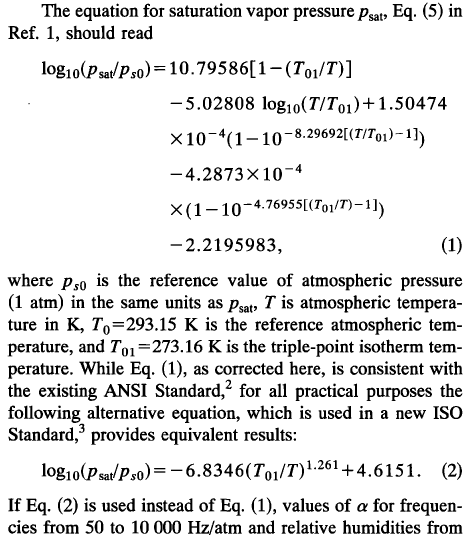- Bass, H. E., et al. (1995)

ps_ps0=ps/ps0;
h = hr*psat_ps0/ps_ps0; % h is the humidity in percent molar concentration

- Bass, H. E., et al. (1995)

h_iso = hr*psat_ps0_iso/ps_ps0; % h is the humidity in percent molar concentration
c0 = 331; % c0 is the reference sound speed
c = (1+0.16*h/100)*c0*sqrt(T/T01);
c_iso = (1+0.16*h_iso/100)*c0*sqrt(T/T01);
% % 
% % **********************************************************************
%  
% 
% Bass formula
F=f/ps;
Fr0=1/ps0*(24+4.04*10^4*h*(0.02+h)/(0.391+h));

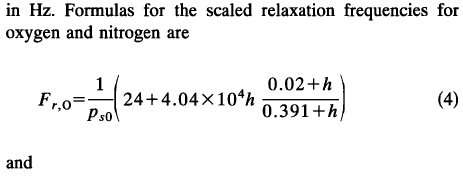- Bass, H. E., et al. (1995)

FrN=1/ps0*(T0/T)^(1/2)*(9+280*h*exp(-4.17*((T0/T)^(1/3)-1)));

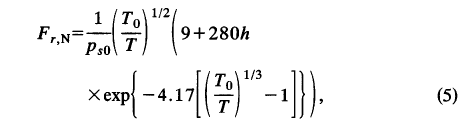- Bass, H. E., et al. (1995)

% Calculate the air absorption in dB/meter using the Bass formula
% alpha=20*log10(exp(1))*ps*F^2*( 1.84*10^(-11)*(T/T0)^(0.5)*ps0+((T/T0)^(-5/2))*( 0.01278*exp(-2239.1/T)/(Fr0+F^2/Fr0)+0.1068*exp(-3352/T)/(FrN+F^2/FrN) ));
alpha=20*log10(exp(1))*ps*F.^2.*( 1.84*10^(-11)*(T/T0)^(0.5)*ps0+((T/T0)^(-5/2))*( 0.01278*exp(-2239.1/T)./(Fr0+F.^2/Fr0)+0.1068*exp(-3352/T)./(FrN+F.^2/FrN) )); % by WJ

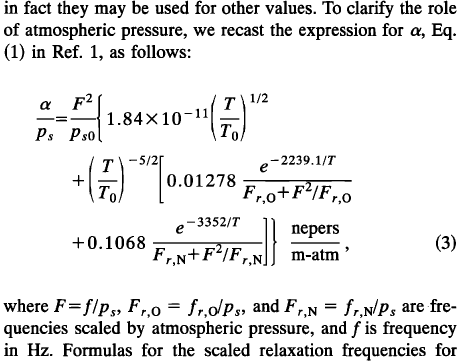- Bass, H. E., et al. (1995)

% % 
% % **********************************************************************
%  
% 
%ISO formula
taur=T/T0;
pr=ps/ps0;
fr0=pr*(24+40400*h_iso*(0.02+h_iso)/(0.391+h_iso));
frN=pr*(taur)^(-1/2)*(9+280*h_iso*exp(-4.17*((taur)^(-1/3)-1)));

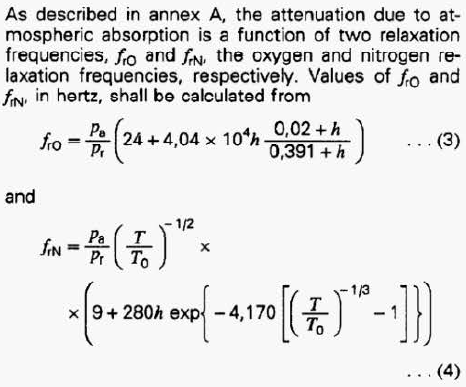- ISO 9613-1:1993

% b1=0.1068*exp(-3352/T)/(frN+f^2/frN);
b1=0.1068*exp(-3352/T)./(frN+f.^2/frN);                                 % by WJ
% b2=0.01275*exp(-2239.1/T)/(fr0+f^2/fr0);
b2=0.01275*exp(-2239.1/T)./(fr0+f.^2/fr0);                              % by WJ
% Calculate the air absorption in dB/meter for the ISO standard
% alpha_iso=8.686*f^2*taur^(1/2)*(1.84*10^(-11)/pr+taur^(-3)*(b1+b2));
alpha_iso=8.686*f.^2*taur^(1/2).*(1.84*10^(-11)/pr+taur^(-3)*(b1+b2));  % by WJ

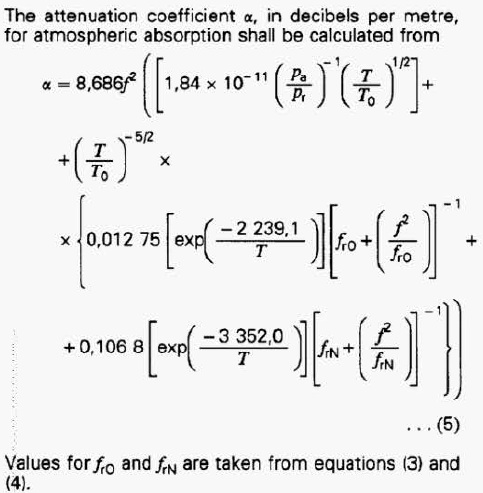- ISO 9613-1:1993

end